# Event Distribution

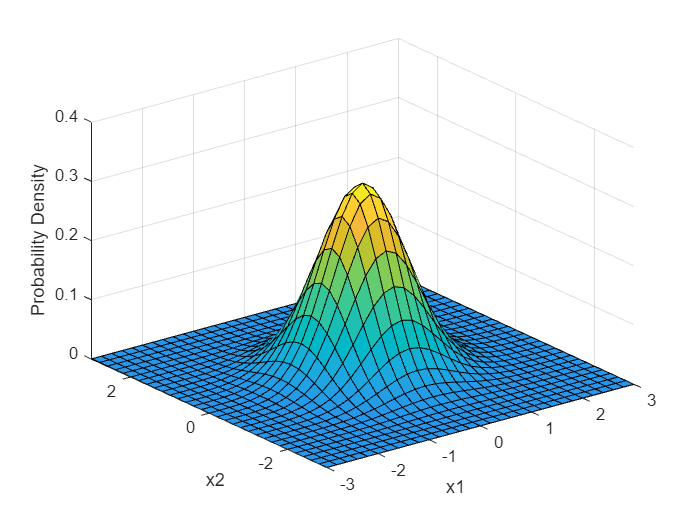

clear;clc;close;

mu = [0 0];
Sigma = [0.5 0.0;0.0 0.5];

x1 = -3:0.2:3;
x2 = -3:0.2:3;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];

y = mvnpdf(X,mu,Sigma);
y = reshape(y,length(x2),length(x1));

surf(x1,x2,y);
clim([min(y(:))-0.5*range(y(:)),max(y(:))]);
axis([-3 3 -3 3 0 0.4]);
xlabel('x1');
ylabel('x2');
zlabel('Probability Density');

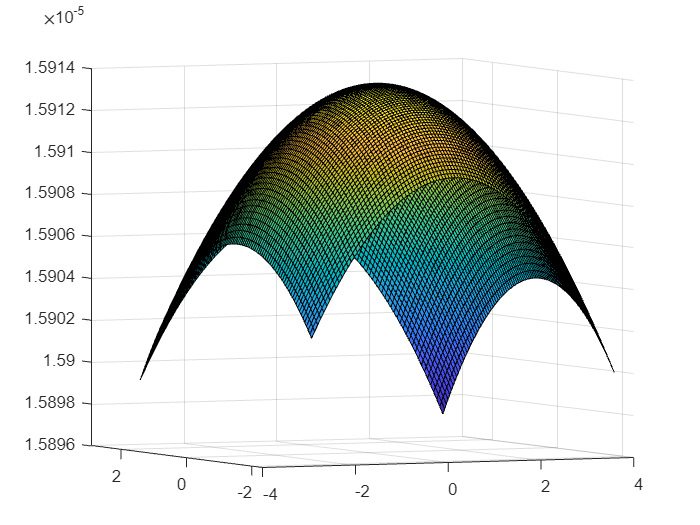

% generate some sample data
x = randn(100,1);
y = randn(100,1);

% create a grid of points to evaluate the density
xgrid = linspace(min(x), max(x), 100);
ygrid = linspace(min(y), max(y), 100);
[X,Y] = meshgrid(xgrid, ygrid);
xy = [X(:) Y(:)];

% estimate the density using a Gaussian kernel
k = 100;  % bandwidth parameter
f = ksdensity([x y], xy, 'Bandwidth', k);

% plot the density surface
surf(X, Y, reshape(f, size(X)));